### Esplorazione area di lavoro

close all
clear
clc

Valori dei parametri caratteristici del manipolare:

params = [1, 1, 0.5, 1, 1, 1, 0.5, 1];                  %vettore dei parametri caratteristici del robot (m1 a1 l1 I1 m2 a2 l2 I2)

Condizioni di riposo iniziale:

pA = [2; 0];                                            %coordinate punto A
qA = inverse_kinematics(pA, 1, params);                 %cinematica inversa punto A
q = [qA(1); qA(2)];                                     %condizioni inziali (angoli e velocità)
dq  = [0; 0];
ddq = [0; 0];

Inizializzo le variabili di errore:

e = zeros(2,1);                                         %errore
de = -dq;                                               %derivata dell'errore

Definisco dominio del tempo per poi risolvere la dinamica:

dt = 0.01;                                              %controllo a 100 Hz

Guadagni  regolatore:

kp = 20;                                                %guadagno regolatore parte proporzionale
kd = 2*sqrt(kp);                                        %guadagno regolatore parte derivativa

Variabili utili per il codice:

nmax = 1500;                                            %numero max cicli
npos = 100;                                             %numero posizionamenti

Inizializzo matrice di memorizzazione delle posizioni:

Mm = zeros(npos,2);                                     %matrice contenente q

Esplorazione dell'area di lavoro:

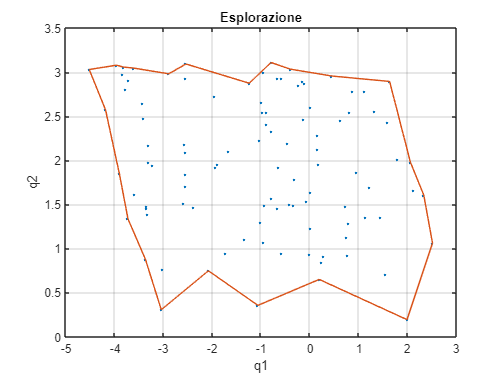

for pos = 1:npos
    qA = q;
    pB = random_pos(params);                            %coordinate punto B
    qB = inverse_kinematics(pB, 1, params);             %cinematica inversa punto B
    e = qB - qA;                                        
    de = -dq;
    run_loop = 1;                                       %condizione cicli
    i = 0;                                              %indice cicli
    while run_loop && i < nmax
        i = i+1;

        % Dinamica diretta
        tau = kp.*e + kd.*de;                                            %ingresso di controllo
        [B, C, g] = get_dynamics(q,dq,params);                           %vettore contenente [B,C,g]
        n = C*dq + g;
        torque_control = computed_torque_control(dq,tau,B, C, g);        %vettore coppia di controllo
        invB = pinv(B);

        % Integration step
        ddq = pinv(B)*(torque_control-n);
        dq  = dq + ddq*dt;
        q   = q + dq*dt;
    
        % Aggiornamento errore
        e = qB - q;
        de = -dq;

        % Salvataggio dati intermedi
        res_robot1(i,:) = q;

        % Condizioni fine ciclo
        if norm(e) < 0.01 && norm(de) < 0.001
            run_loop = 0;
        end
    end

    %costruzione matrice con coordinate lagrangiane
    Mm(pos,1:2) = q;
    x = Mm(:,1);
    y = Mm(:,2);

    %contorno posizioni raggiunte
    c = zeros;
    if pos >= 3
        c = boundary(x,y);                                                  %

    %costruzione bordi
    cl = length(c);
    for nn1 = 1:cl-1
        
        p1 = c(nn1);                                                        %pedice punto 1
        p2 = c(nn1+1);                                                      %pedice punto 2

        h(nn1,1) = (y(p2) - y(p1))/(x(p2) - x(p1));                         %coeff angolare 1
        h(nn1,2) = -1;                                                      %coeff angolare 2
        h(nn1,3) = y(p1) - (y(p2) - y(p1))/(x(p2) - x(p1))*x(p1);           %intercetta asse y

    end

    H = 2*eye(2);
    f = - 2 * computed_torque_control(dq,tau,B, C, g)';
    A = zeros(cl,2);
    b = zeros(cl,1);
    gamma1 = 1;
    gamma2 = 2;
    for ii = 1:cl-1
        mi = h(ii,1:2);
        bi = h(ii,3);
        A(ii,1:2) = mi*invB;
        b(ii) = - gamma1*(mi*q + bi) - gamma2*(mi*dq) + (mi*invB)*n;
    end
    u = quadprog(H, f, A, b, ...
        [], [], [], [], [], optimoptions('quadprog','Display','off'));
    end
end

figure
plot(x,y,'.')
hold on
plot(x(c),y(c))
grid on
title('Esplorazione')
xlabel('q1')
ylabel('q2')


%verifica che punto sul bordo fa 0:
hi = h(1,1:2)*[x(c(1)); y(c(1))] + h(1,3)

hi = 0